Gaussiano

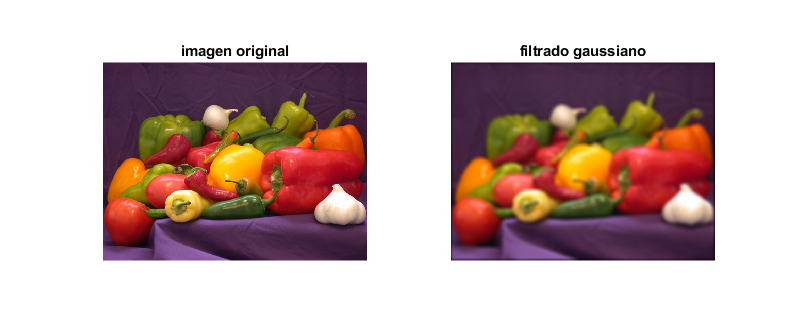

im = imread('peppers.png');
subplot(1,2,1)
imshow(im), title('imagen original');
h = fspecial('gaussian',10,4);
imgauss = imfilter(im,h,'conv');
subplot(1,2,2);
imshow(imgauss), title('filtrado gaussiano');

Median

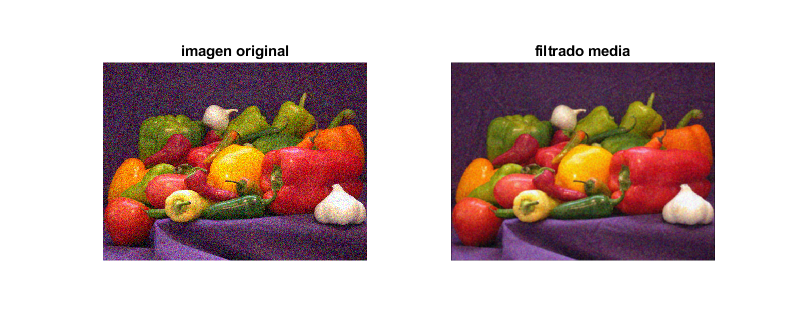

im = imread('peppers.png');
im = imnoise(im,'gaussian'); 
subplot(1,2,1)
imshow(im), title('imagen original');
h = fspecial('average',3);
imfilt = imfilter(im,h);
subplot(1,2,2)
imshow(imfilt), title('filtrado media');

Mediana

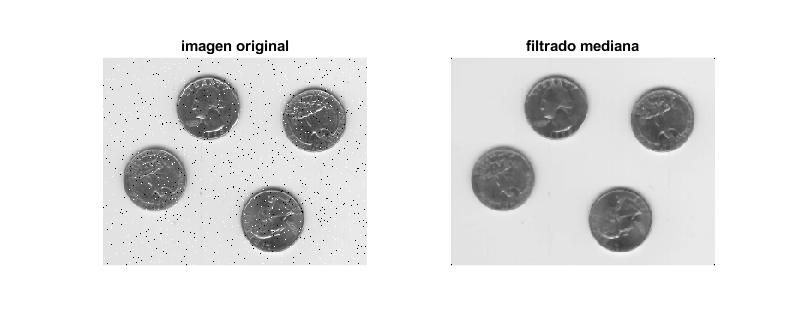

I = imread('eight.tif');
J = imnoise(I,'salt & pepper',0.02);
K = medfilt2(J);
subplot(1,2,1)
imshow(J), title('imagen original');
subplot(1,2,2)
imshow(K), title('filtrado mediana');